# Homework 1: HIV Drug Response

In this homework, you will analyze data from HIV patients. Patients receiving different therapy regimens were monitored for their blood viral load. You are asked to determine which therapy regimen provides the best treatment.

## Description of Data

The file patientdata.xlsx contains patient data collected from 5000 HIV patients.

- Column-1 represents the patient's Age at intake

- Column-2 represents the drug regimen

- Column-3 represents the Viral Load (copies/mL) at intake

- Column-4 to Column-8 is the Viral Load measured at** 6 month** intervals.

- Drug-regimen #1 is a **placebo control**.

## Variable names and acronyms used in this file

- **m**: The patient data matrix, each row is a patient and columns are as described above.

- **vl**: Viral load.

- **dvl**: Change in viral load.

- The terms group/drug/treatment are used interchangeably.

## Objectives:

- Understand the data

- Read an excel file into a cell array with xlsread()

- Use logical index array to select certain data. 

- Plot, captions and conclusions

## **  Best practice:**

- comment out all the example codes 

## Read the patient data file

% xlsread is slow and tends to cause compatibility issuses. So instead,
% I'll use readtable which will return the data as a table object.
T = readtable('patientdata.xlsx');
% Extract the fields as a cell array
fields = T.Properties.VariableNames;
fields

fields = 1×8 cell array
    {'age'}    {'drugregimen'}    {'viralload0'}    {'viralload1'}    {'viralload2'}    {'viralload3'}    {'viralload4'}    {'viralload5'}

% Extract numeric data as a matrix
m = table2array(T);

# Check to make sure the groupings/drug regiment are random in age

The goal of this section is to  find the average age of individuals on different drug regiments (age column and drugregimen column). The template codes are listed below. The key is to  generate the 500x1 logical index based on drugregimens (who are taking drug 1,....), then use the logical index I to select the individuals and calculate average age in the age column. 

% Create logical arrays for selecting columns
regimencol = strcmpi(fields, 'drugregimen');
agecol = strcmpi(fields, 'age');
% Calculate mean age of all patients
avg_age = mean(m(:, agecol));
fprintf('The average age of patients in the study is %g', avg_age)

The average age of patients in the study is 41.36

% What are the different drug regiment groups?
regiments = unique(m(:, regimencol));

% To improve the efficieny of the code, I've vectorized all steps that would require
% for loops to calculate parameters by group. This was achieved using the 
% splitapply(@fun, m, g) function which applies a function fun to sections of the input 
% data matrix m based on groups specified by g. It's functionality is analagous to
% group_by operations in other languages.

% Find the average age of patients broken down by drug-regiment
avg_groupage = splitapply(@mean, m(:, agecol), m(:, regimencol));
% Find the average age of patients broken down by drug-regiment
std_groupage = splitapply(@std, m(:, agecol), m(:, regimencol));

## Plot Age Data

Put this data into a bar-plot. Do you notice anything? How would you be able to tell if the data was askew? 

- If the data were askew, the average age for one of the groups would be significantly different (higher or lower) from the others.

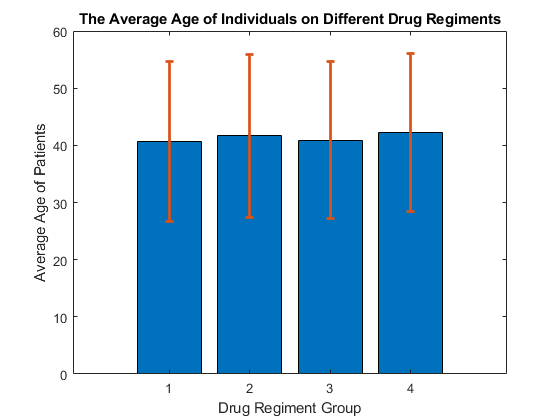

figure;
bar(regiments, avg_groupage);
hold on;
errorbar(regiments, avg_groupage, std_groupage, 'LineStyle', 'none', 'LineWidth', 2);
hold off;
xlabel('Drug Regiment Group');
ylabel('Average Age of Patients');
title('The Average Age of Individuals on Different Drug Regiments');

### Captions

**The Average Age of Individuals on Different Drug Regiments**

A bar plot showing the average ages of patients treated with different drug regiments (blue bars) overlayed by errorbars (in red) showing the standard deviations of ages in each group.

### Conclusions 

The figure shows that the average age across all groups is (roughly) the same.

## Plot Age Distributions

 What else could you include to help visualize any potential differences? what about a histogram? 

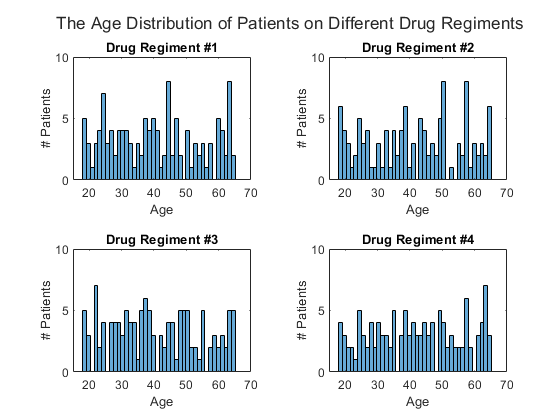

% Next, we'll visualize the age distributions on the different drug
% regiment groups
figure;
t = tiledlayout('flow');
for i = 1:numel(regiments)
	nexttile;
	% m(:, regimencol) == i selects all rows where drugregimen == i
	histogram(m(m(:, regimencol) == i, agecol), 40);
	title(sprintf('Drug Regiment #%g', i));
	xlabel('Age');
	ylabel('# Patients');
	axis([15 70 0 10])
end
title(t, 'The Age Distribution of Patients on Different Drug Regiments');

### Captions

**The Age Distribution of Patietns on Different Drug Regiments**

This figure shows histograms showing the number of patients grouped by their ages.

### Conclusions 

These figures appear to show that the age distribution in each group is fairly random. Drug regiment #4 seems to be sligtlhy skewed to the right (skewed towards older patients).

## *Runs Test* for Randomness

Finally, I will employ runs test for randomness to validate my observations from the figures. The test will be run using the mean of each group as the reference value, and at a significance level of $\alpha = 0.01$.

`runstest()` returns the hypothesis test results, `h`. 

- `h = 1: ``Null hypothesis rejected; variable is not random.`

- `h = 0: ``Failed to reject null hypothesis; variable is random.`

myRunsTest = @(x) runstest(x, mean(x), 'alpha', 0.01);
[~, p] = splitapply(myRunsTest, m(:, agecol), m(:, regimencol))

p =     0.2957
    1.0000
    0.1998
    0.0539


### Conclusions

Since $p > \alpha = 0.01$ for all groups, we can conclude that - at a significance level of $0.01$- the ages of patients in each drug regiment group are randomly distributed.

# Check to make sure the groupings are random in initial health (viralload0).

It is important to note that you should use **log-scale** values when looking at viral loads

% Logical array for selecting viralload0 column
vl0_col = strcmpi(fields, 'viralload0');
% Compute average viralload0 of patients broken down by drug-regiment
log_avg_group_vl0 = splitapply(@(x) mean(log10(x)), m(:, vl0_col), m(:, regimencol));
% Compute std of viralload0 of patients broken down by drug-regiment
log_std_group_vl0 = splitapply(@(x) std(log10(x)), m(:, vl0_col), m(:, regimencol));

## Plot Viral Load Data

Put this data into a bar-plot, do you notice anything? How would you be able to tell if the data was askew. What else could you include to help visualize any potential differences?

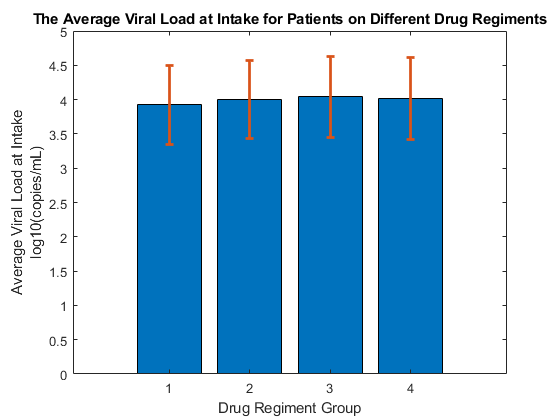

figure;
bar(regiments, log_avg_group_vl0);
hold on;
errorbar(regiments, log_avg_group_vl0, log_std_group_vl0, 'LineStyle', 'none', 'LineWidth', 2);
hold off;
xlabel('Drug Regiment Group');
ylabel({'Average Viral Load at Intake'; 'log10(copies/mL)'});
title('The Average Viral Load at Intake for Patients on Different Drug Regiments');

### Captions

**The Average Viral Load at Intake for Patients on Different Drug Regiments**

A bar plot showing the average viral load of patients at intake overlayed by the error bars showing the standard deviation of viral loads in each group.

### Conclusions 

The average viral load at intake is (roughly) the same across all groups.

## Plot Viral Load Distributions

How would you be able to tell if the data was askew. What else could you include to help visualize any potential differences? try to plot in a histogram

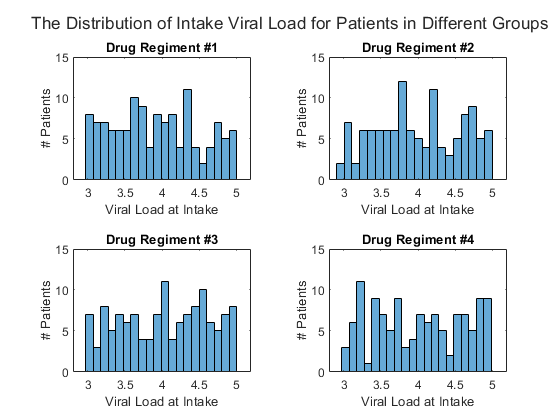

figure;
% Next, we'll visualize the distribution of intake viral load for patients on the
% different drug regiments
figure;
t = tiledlayout('flow');
for i = 1:numel(regiments)
	nexttile;
	% m(:, regimencol) == i selects all rows where drugregimen == i
	histogram(log10(m(m(:, regimencol) == i, vl0_col)), 20);
	title(sprintf('Drug Regiment #%g', i));
	xlabel('Viral Load at Intake');
	ylabel('# Patients');
	axis([2.8 5.2 0 15])
end
title(t, 'The Distribution of Intake Viral Load for Patients in Different Groups');

### Captions

**The Distribution of Intake Viral Load for Patients in Different Groups**

Histograms showing the number of patients grouped by their intake viral load.

### Conclusions 

These figures appear to show that the intake viral load distribution in each group is fairly random.

## *Runs Test* for Randomness

Finally, I will employ runs test for randomness to validate my observations from the figures. The test will be run using the mean of each group as the reference value, and at a significance level of $\alpha = 0.01$.

`runstest()` returns the hypothesis test results, `h`. 

- `h = 1: ``Null hypothesis rejected; variable is not random.`

- `h = 0: ``Failed to reject null hypothesis; variable is random.`

myRunsTest = @(x) runstest(x, mean(x), 'alpha', 0.01);
[~, p] = splitapply(myRunsTest, m(:, vl0_col), m(:, regimencol))

p =     1.0000
    0.3420
    1.0000
    0.2300


### Conclusions

Since $p > \alpha = 0.01$ for all groups, we can conclude that - at a significance level of $0.01$- the initial viral loads of patients in all four groups are randomly distributed.

# Which therapy worked best?

# Evaluate therapies by fraction of minimum detectable level patients

We'll look at how many patients decreased to the minumum detectable level of viral load. In this dataset that's 48 copies/mL.

% Logical array for selecting the viral load at final timepoint.
vl5_col = strcmpi(fields, 'viralload5');
% What fraction of patients were at the minimum detection threshold at the
% final timepoint?
cured = sum(m(:, vl5_col) <= 48) / numel(m(:, vl5_col)) * 100;
fprintf(['%.2f%% of Patients were "cured" (at or below the minimum detection ' ...
	       'threshold) at the final timepoint.'], cured)

13.20% of Patients were "cured" (at or below the minimum detection threshold) at the final timepoint.

## Plot Ratios of Patients at Minimum Detection

When you plot these, what do you see? Which treatment is the most effective by this measure? The ratio should be the total number of individuals with less than 48 viralloads over the total number of patients in this group. 

- Drug regiment 4 is the most effective of the treatments, however it is not as effective as the control (Drug Regiment 1).

% Number of patients at or below 48 copies/mL in each group
% Create a logical array for selecting all viral load columns
vls = ~cellfun(@isempty, regexp(fields, "viralload"));
% Extract only viral load columns
viralload = m(:, vls);
% Find all patients with viral loads <= 48
cured = any( viralload <= 48, 2);
% Determine the cured ratio for each group
grp_curedratio = splitapply(@(x) sum(x) / numel(x), cured, m(:, regimencol))

grp_curedratio =     0.1473
    0.1261
    0.1308
    0.1393


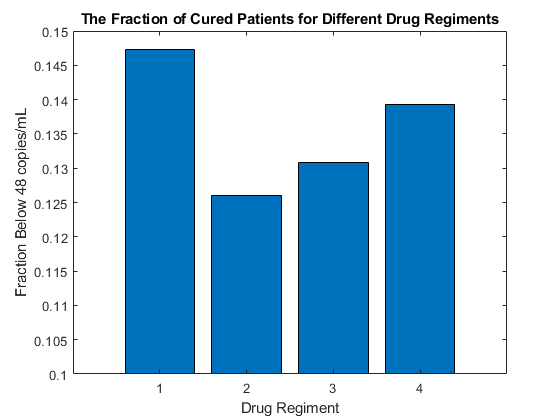

% Plot the cured ratios for each group
figure;
bar(regiments, grp_curedratio);
ylabel('Fraction Below 48 copies/mL');
xlabel("Drug Regiment"); 
% Scale the axes to better visualize the differences between groups
axis([0 5 0.1 0.15]);
title('The Fraction of Cured Patients for Different Drug Regiments');

### Captions

**The Fraction of Cured Patients for Different Drug Regiments**

A bar plot showing the fraction of patients who had viral loads less than 48 copies/mL.

### Conclusions 

Drug regiment #4 appears to be the most effective of the treatments with $13.93\%$ of patients on this regiment being 'cured' (i.e. having a viral load $<=~48~copies/mL$). Although, the control (Drug Regiment #1) seems to have been more effective than any of the treatments with $14.73\%$ of patients in that group being cured.

# Which therapy worked best?

# Evaluate therapies by rate of change.

Another way to measure the effectiveness of the therapies is to look at the rate of change induced as a function of therapy. For this, we will use the diff**()** function in Matlab. Calculate the difference between each month (each visit) and compare the average across the different drug groups.

The 500x6 will change to 500X5.   

% for each patient over all time points.
% Units: log10(copies/mL)/month
patientdvl = diff(log10(viralload), 1, 2);

% Compute average rates of change for each group
groupdvl = splitapply(@(x) mean(x, 1), patientdvl, m(:, regimencol));
groupd_std_vl = splitapply(@(x) std(x, 1), patientdvl, m(:, regimencol));

## Plot Rate of Change in Viral Load

When you plot these, what do you see? Which treatment is the most effective by this measure?

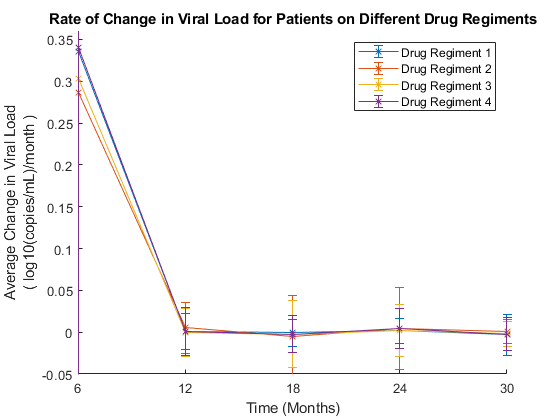

figure;
hold on
for gi = 1:numel(regiments)
	I = m(:, regimencol) == gi;
	% Plot the rate of change against the time passed
	% % There are 5 timepoints at 6 month intervals -> 6:6:30
	errorbar(6 * (1:5), -groupdvl(gi, :), groupd_std_vl(gi, :), '-x');
end
xlabel('Time (Months)')
ylabel({'Average Change in Viral Load';'( log10(copies/mL)/month )'})
legend('Drug Regiment 1', 'Drug Regiment 2', 'Drug Regiment 3', 'Drug Regiment 4')
title('Rate of Change in Viral Load for Patients on Different Drug Regiments')
xticks([6 12 18 24 30])
axis([6 30 -0.05 0.36])

## Captions

**Rate of Change in Viral Load for Patients on Different Drug Regiments**

This figure shows line graphs indicating the average rate of change in viral load after each 6-month period for the different groups. It also shows errorbars indicating the standard deviations of the rates of change after each month.

## Conclusions

All drug regiments, including the control appear to be most active within the first month, with activity decreasing in the following months. Drug regiments 1 (control) and 4 have the strongest impact on viral load.

# Bonus to A+: (5 points)

What about using polyfit() to caculate the rate of change between months,  and plot the average slope of each drugregimen. 

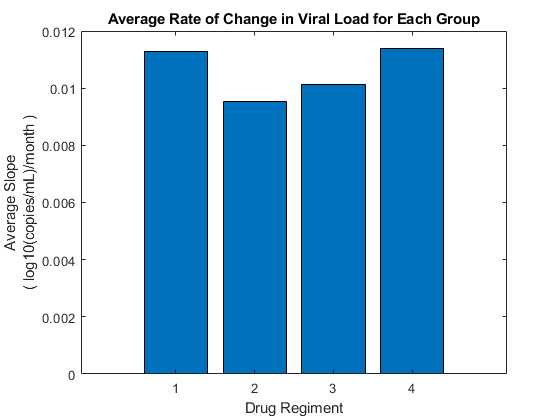

% Compute slopes by fitting the change in viral load (dvl) against each
% timepoint (6:6:30)
fit = splitapply(@(x) polyfit(6 * (1:5), x, 1), groupdvl, regiments);
% Plot average rates of change in viral load
figure;
bar(regiments, fit(:, 1))
xlabel('Drug Regiment')
ylabel({'Average Slope';'( log10(copies/mL)/month )'})
title(['Average Rate of Change in Viral Load for Each Group']);

### Captions

A bar plot showing the average rate of change in viral load with respect to time (slope) for each of the drug regiments.

### Conclusions

The figure reinforces prior inferences that Drug Regiments 1(control) and 4 outperform the other treatments since they reduce the viral load the quickest (have the steepest slopes).